# Chapter 3. Interpolation and Polynomial Approximation

## 3.1 Interpolation and the Lagrange Polynomial

### Theorem 3.2

If $x_0,\ x_1,\ \cdots,\ x_n$ are $n+1
$ distinct numbers and $f$ is a function whose values are given at these numbers, then a unique polynomial $P(x)$ of degree at most $n$ exists with


$$f(x_k) = P(x_k),\qquad \text{for each}\ k = 0,1,\cdots,n.$$


This polynomial is given by


$$P(x) = f(x_0) L_{n,0}(x) + \cdots + f(x_n) L_{n,n}(x) = \sum_{k=0}^n f(x_k) L_{n,k}(x),$$


where, for each $k=0,1,\cdots,n$,


$$L_{n,k}(x) = \frac{(x-x_0)(x-x_1)\cdots(x-x_{k-1})(x-x_{k+1})\cdots(x-x_n)}{(x_k-x_0)(x_k-x_1)\cdots(x_k-x_{k-1})(x_k-x_{k+1})\cdots(x_k-x_n)} = \prod_{i=0,\ i\neq k}^n \frac{(x-x_i)}{(x_k - x_i)}.$$


### Example 2

Use the numbers (called nodes) $x_0 = 2,\ x_1 = 2.75$, and $x_2 = 4$ to find the second Lagrange interpolating polynomial for $f(x) = 1/x$ and approximate $f(3) = 1/3$.

x = [2, 2.75, 4];
fval = 1./x;
t = 3;
val = Lagrange_polynomial(t,x,fval);
sprintf('%.5f',val)
t = linspace(0.2,5.2,200);
val = zeros(size(t));
for j = 1:length(val)
    val(j) = Lagrange_polynomial(t(j),x,fval);
end
figure()
plot(t,1./t,'b-',linewidth=2)
hold on
plot(t,val,'r-',linewidth=2)
plot(x,1./x,'ko',markersize=8,markerfacecolor='k')
legend('y = 1/x', 'Lagrange Interpolating Polynomial')
title(sprintf('Lagrange Interpolating Polynomial with x_0 = %.2f, x_1 = %.2f, and x_2 = %.2f',x(1),x(2),x(3)))

## 3.5 Cubic Spline Interpolation

### **Natural Cubic Spline**

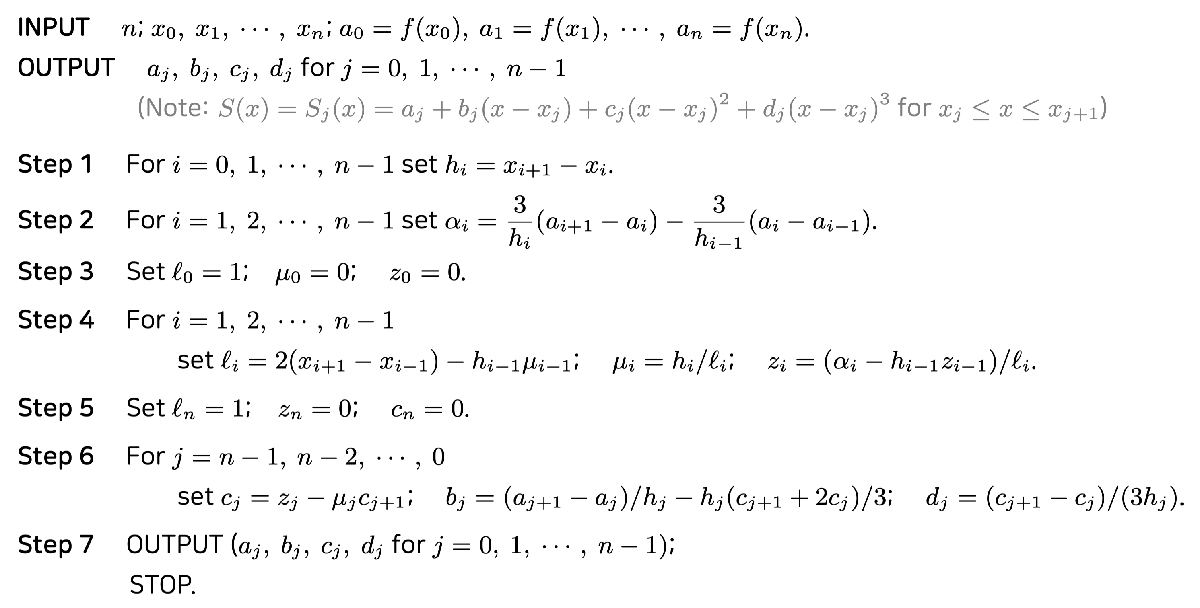

### Example 2

Use the data points $(0,1),\ (1,e),\ (2,e^2)$, and $(3,e^3)$ to form a natural spline $S(x)$ that approximates $f(x) = e^x.$	

n = 3;
x = [0,1,2,3];
fval = exp(x);
[a,b,c,d] = natural_cubic_spline(n,x,fval);
fprintf(' a: [%s]\n b: [%s]\n c: [%s]\n d: [%s]', join(string(a), ','), join(string(b), ','), join(string(c), ','), join(string(d), ','));
nodes = linspace(0,3);
fval = evaluate_cubic_spline(nodes,x,a,b,c,d);
figure()
plot(nodes,exp(nodes),'b-',linewidth=2);
hold on
plot(nodes,fval,'r-',linewidth=2)
plot(x,exp(x),'ko',markersize=8,markerfacecolor='k')
legend('$y = e^x$', 'Natural cubic spline','Interpreter','latex','location','northwest')
title(sprintf('Natural Cubic Spline with n = %d',n))
x = [0,0.5,1,1.5,2,2.5,3];
n = length(x)-1;
fval = exp(x);
[a,b,c,d] = natural_cubic_spline(n,x,fval);
nodes = linspace(0,3);
fval = evaluate_cubic_spline(nodes,x,a,b,c,d);
figure()
plot(nodes,exp(nodes),'b-',linewidth=2);
hold on
plot(nodes,fval,'r--',linewidth=2)
plot(x,exp(x),'ko',markersize=8,markerfacecolor='k')
legend('$y = e^x$', 'Natural cubic spline','Interpreter','latex','location','northwest')
title(sprintf('Natural Cubic Spline with n = %d',n))

### Clamped Cubic Spline

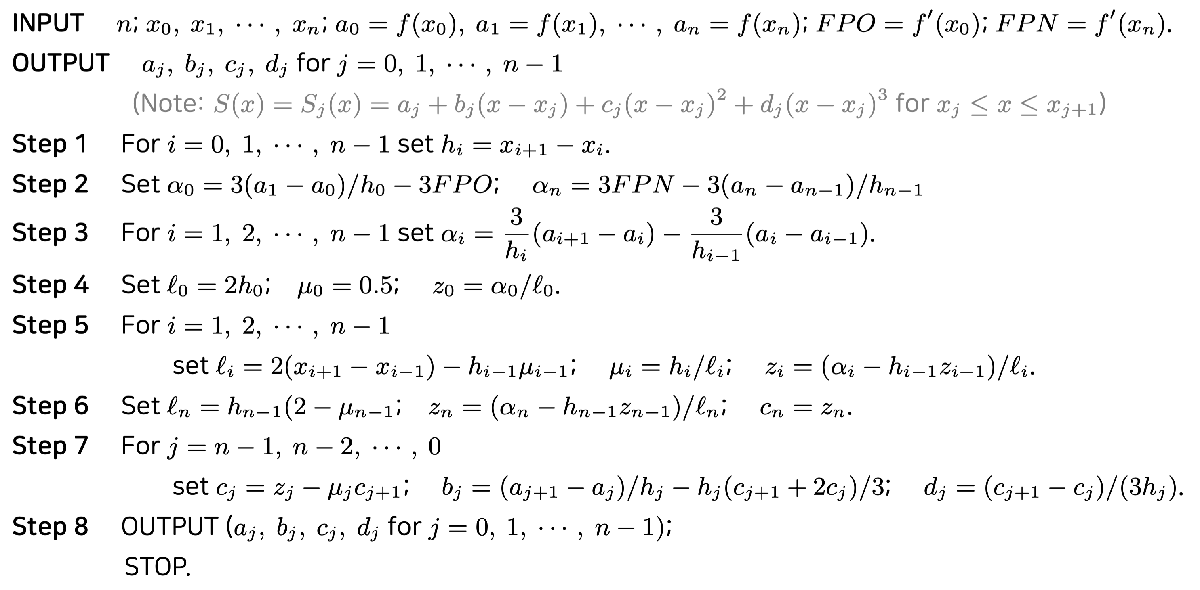

### Example 4

Example 2 used a natural spline and the data points $(0,1),\ (1,e),\ (2,e^2),$ and $(3,e^3)$ to form a new approximating function $S(x)$. Determine the clamped spline $s(x)$ that uses this data and the additional information that, since $f'(x) = e^x$, so $f'(x) = 1$ and $f'(e) = e^3$.

n = 3;
x = [0,1,2,3];
fval = exp(x);
FPO = 1;
FPN = exp(3);
[a,b,c,d] = clamped_cubic_spline(n,x,fval,FPO,FPN);
fprintf(' a: [%s]\n b: [%s]\n c: [%s]\n d: [%s]', join(string(a), ','), join(string(b), ','), join(string(c), ','), join(string(d), ','));
nodes = linspace(0,3);
fvalc = evaluate_cubic_spline(nodes,x,a,b,c,d);
figure()
plot(nodes,exp(nodes),'b-',linewidth=2);
hold on
plot(nodes,fvalc,'r--',linewidth=2)
plot(x,exp(x),'ko',markersize=8,markerfacecolor='k')
legend('$y = e^x$', 'Clamped cubic spline','Interpreter','latex','location','northwest')
title(sprintf('Clamped Cubic Spline with n = %d',n))
[an,bn,cn,dn] = natural_cubic_spline(n,x,fval);
fvaln = evaluate_cubic_spline(nodes,x,an,bn,cn,dn);
figure()
plot(nodes,exp(nodes),'b-',linewidth=2);
hold on
plot(nodes,fvalc,'r--',linewidth=2)
plot(nodes,fvaln,'k--',linewidth=2)
plot(x,exp(x),'ko',markersize=8,markerfacecolor='k')
legend('$y = e^x$', 'Clamped cubic spline', 'Natural cubic spline', 'Interpreter','latex','location','northwest')
title(sprintf('Natural and Clamped Cubic Spline with  with n = %d',n))